# 3301 Major Project Optimisation

clearvars;

## Read in the data and do some preprocessing

dateFormat = "dd/MM/yyyy HH:mm";
analYear = 2021;

% It seems matlab already reads in .csv automatically with date-times, nice
nemData = readtable("20211008 OpenNEM.csv");


% There seems to be a "energy requirement" column in this that may be
% useful when calculating how much energy the battery loses
rawCarData = readtable("08G0VZET.csv");


% make the format consistent
nemData.date.Format = dateFormat;
rawCarData.datetime.Format = dateFormat;

% Make the datasets have the same year
nemData.date.Year = analYear;
rawCarData.datetime.Year = analYear;

% The NEM data is much smaller than the car data, so we extract the car
% data rows which allign with the NEM data
idx = ismember(rawCarData.datetime, nemData.date);
carData = rawCarData(idx, :);

% Sanity check, these should have the same size and starting dates
length(nemData.date) == length(carData.datetime)

ans = logical
   1


nemData.date(1) == carData.datetime(1)

ans = logical
   1



% Convert NEM data to $ per kWh
nemData.Price_AUD_kWh = nemData.Price_AUD_MWh * 1e-3;

## Define objective function

prices = nemData.Price_AUD_kWh;
availability = carData.available;

onPeak = 0.1

onPeak = 0.1000

offPeak = -0.000001

offPeak = -1.0000e-06


hours = hour(carData.datetime)

hours =     12
    12
    12
    12
    12
    13
    13
    13
    13
    13


peak = (9 <= hours) & (hours <= 15)

peak = 2017×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1



penalty = onPeak*peak + offPeak*~peak

penalty =     0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000



% Sanity check
flipud(cumsum(penalty))

ans =    58.8986
   58.7986
   58.6986
   58.5986
   58.4986
   58.3986
   58.2986
   58.1986
   58.0986
   57.9986



% The car cannot earn money on the grid while it is out.
decVariables = prices.*availability - flipud(cumsum(penalty))

decVariables =   -58.9650
  -58.8485
  -58.6986
  -58.5986
  -58.4986
  -58.3986
  -58.2986
  -58.1986
  -58.0986
  -57.9986


## Stop car from charging while it is out

unavailability = 1-availability;

Aeq = diag(unavailability);
% It still loses charge from the drive
beq = -carData.energyrequirement; % Discharge is negative

## Charge and discharge limits (sliders in kW)

% Charge limits are removed at the times the car is out
removeLimits = unavailability;
removeLimits(removeLimits==1) = inf;

% Convert kW to the actual amount which can be discharged in 5 mins
discharge = 6.5* (5/60);
lb = -discharge*ones(length(decVariables), 1) - removeLimits;

charge =6.5* (5/60);
ub =  charge*ones(length(decVariables), 1) + removeLimits;

## Capacity Limits

capacity = 40; % 40kW is the nissan leaf battery
start_soc = 0.8; % Car starts with some juice in it

% Stop the car from charging or discharging out of "safe" limits.
lowsoc = 0.2;
highsoc = 0.8;

A_1 = tril(ones(length(decVariables), length(decVariables))) ;
b_1 = ((1-start_soc) * capacity - (1-highsoc)*capacity) * ones(length(decVariables), 1);

## Cant discharge battery below 0

% There may be an edge-case here where the car goes on a trip
% and discharges below the "safe limits" of the battery. If starting soc is
% high, this shouldn't happen.
A_2 = -1*tril(ones(length(decVariables), length(decVariables)));
b_2 = (start_soc*capacity-0.2*capacity)*ones(length(decVariables), 1)

b_2 =     24
    24
    24
    24
    24
    24
    24
    24
    24
    24


## Any energy exported is wasted, dont export

% This isnt needed anymore
% A_3 = -1*eye(24);
% L = tbl.Load;
% S = tbl.Generation;
% b_3 = L-S;

## Add all the constraints to the same matrix

A = cat(1, A_1, A_2);
b = cat(1, b_1, b_2);

## Solve

[B, fval] = linprog(decVariables,A,b,Aeq,beq,lb,ub)

Optimal solution found.



B =          0
         0
   -5.8350
         0
         0
         0
         0
         0
         0
         0


fval = 63.2570


savings = B'*prices

savings = -14.2142

## Benchmarking Against Standard Behaviour

benchmark_charge_behavior = 1:1:length(decVariables);
benchmark_soc = 1:1:length(decVariables);
battery_charge = start_soc*capacity;
for i = 1:length(decVariables)
    if (availability(i) == 1 && battery_charge < capacity)
        if (capacity-battery_charge < ub(1))
            benchmark_charge_behavior(i) = capacity-battery_charge;
        else
            benchmark_charge_behavior(i) = ub(1);
        end
    else
        benchmark_charge_behavior(i) = 0;
    end
    battery_charge = battery_charge + benchmark_charge_behavior(i) - carData.energyrequirement(i);
    benchmark_soc(i) = battery_charge;
end

benchmark_costs = benchmark_charge_behavior*(prices.*availability)

benchmark_costs = 0.2077

## Plots

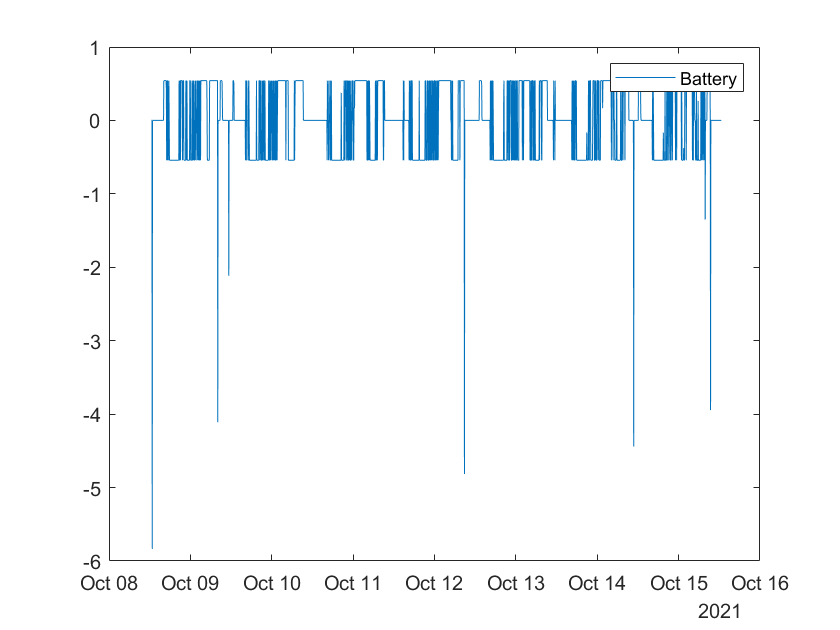

plot(nemData.date, B, 'DisplayName', 'Battery') % looks correct, the spikes are from when the car goes on a trip
legend

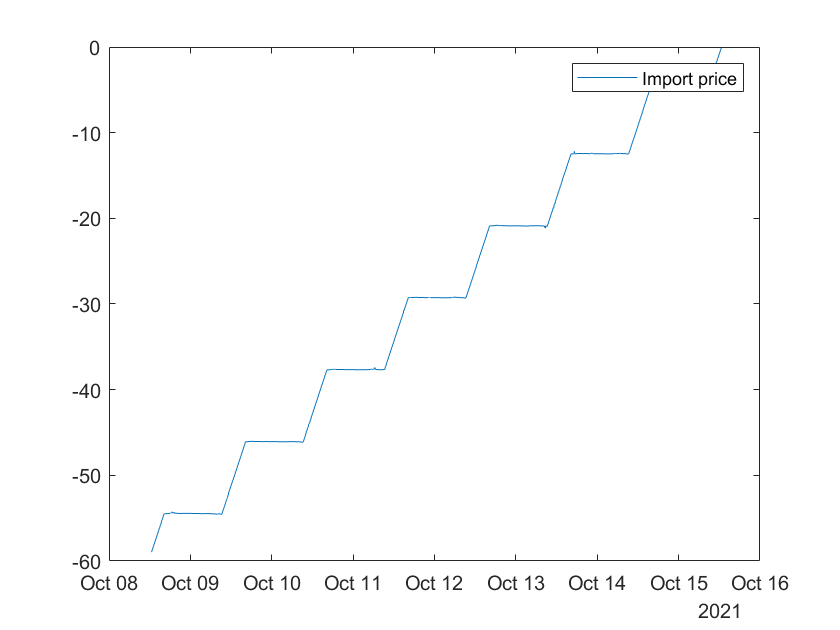

plot(nemData.date,decVariables,'DisplayName','Import price')
legend

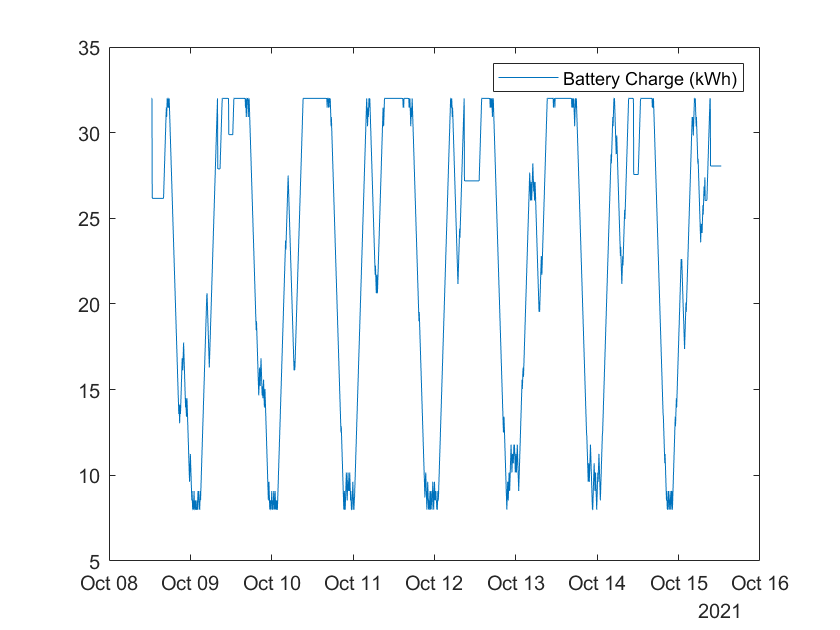

plot(nemData.date, cumsum(B) + start_soc*40,'DisplayName','Battery Charge (kWh)') % looks good, battery keeps within its capacity
legend

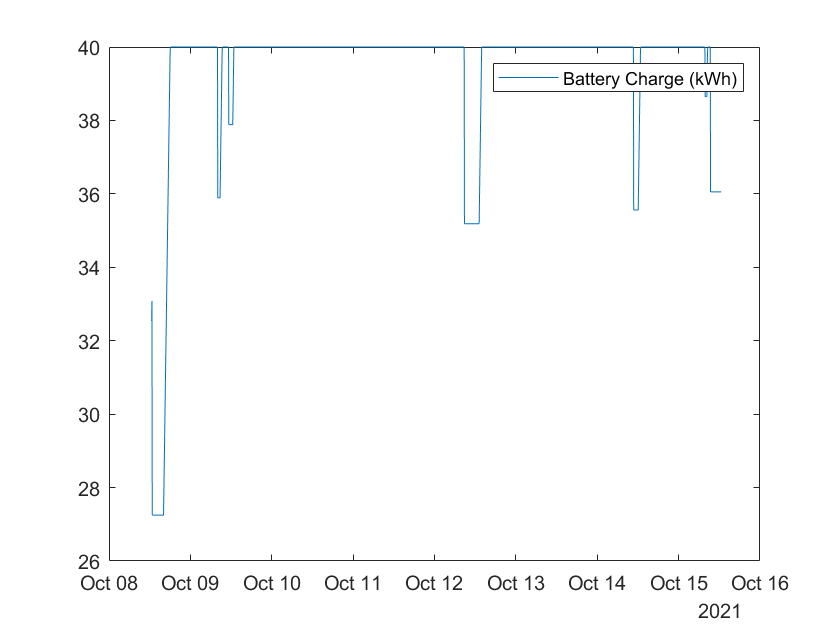


plot(nemData.date, benchmark_soc,'DisplayName','Battery Charge (kWh)') % looks good, battery keeps within its capacity
legend

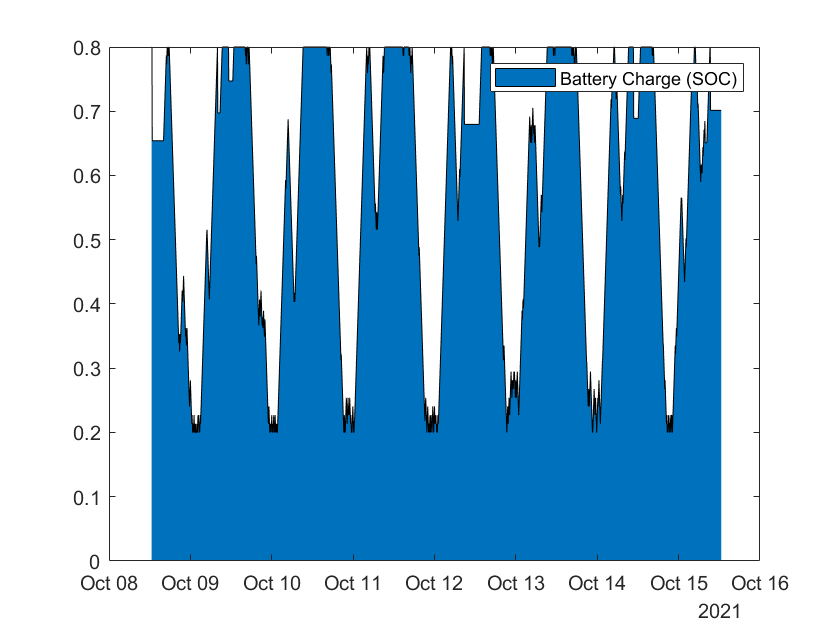

area(nemData.date, (cumsum(B) + start_soc*capacity)/40,'DisplayName','Battery Charge (SOC)') % looks good, battery keeps within its capacity
legend